Lecture Notes

## Constants

clearvars;
c=299792458;


% alpha = 0.2  dB/Km
% For SI: *ln(10)/10 *10^-3 [m^-1]
alpha = 0.2*log(10)*10^-4;  % 1/m

D = 17;                     % ps/nm/km
beta_2 = -D/0.784;           % ps^2/km
%To SI:
beta_2 = beta_2*10^-27;
D = D*10^-6;

gamma = 1.3;                % (km.W)^-1

%For SI: *10^-3
gamma = gamma*10^-3;

z = 40e3;                   % Total Fibre Length (m)
dz = 1e3;                   % Spatial Step (m) 

num_symbols = 32*1024; 
symbol_rate = 32e9;
time_step = 1/symbol_rate;
upsampling = 16;
sample_rate = upsampling*symbol_rate;
num_samples = upsampling*num_symbols;
Ts = 1/sample_rate;
rng(1960);
span=20;
Rolloff=0.1;
receiver_samples_per_symbol = 2;
lambda = 1550e-9;
f_up = (0:num_samples/2-1);
f_down = (-num_samples/2:-1);
fs = [f_up f_down]*symbol_rate/num_symbols;
w = 2*pi*fs.';


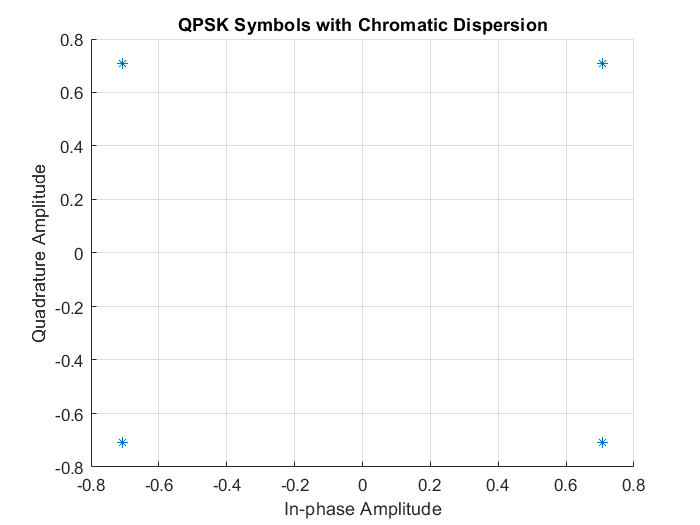

symbols_q = randi([0 3],1,num_symbols);
qpsk_mod = pskmod(symbols_q,4,pi/4,'gray');

figure
scatter(real(qpsk_mod),imag(qpsk_mod),'*');
title("QPSK Symbols with Chromatic Dispersion");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;

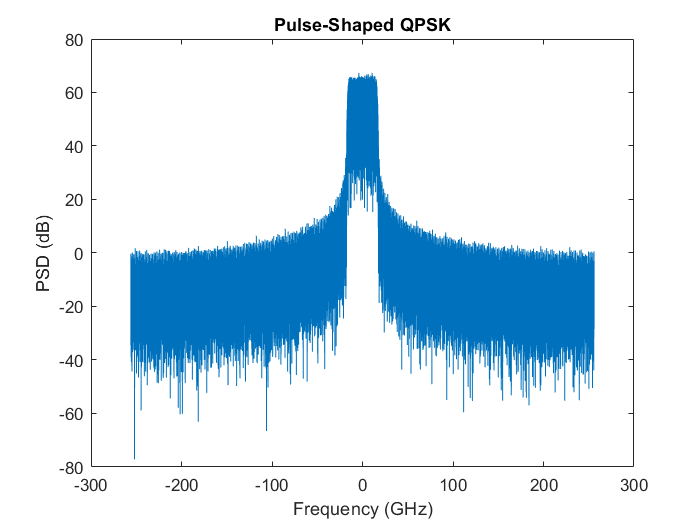


tx_ps_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",span,"OutputSamplesPerSymbol",upsampling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
rx_ps_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",span,"InputSamplesPerSymbol",upsampling,"DecimationFactor",upsampling/receiver_samples_per_symbol,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);

upsampled_qpsk = tx_ps_filter(qpsk_mod.').';

Pxx = ifftshift(fft(upsampled_qpsk).*conj(fft(upsampled_qpsk)));
[~,f] = periodogram(upsampled_qpsk,[],[],sample_rate,'centered');
figure
plot(f/1e9,10*log10(Pxx));
xlabel("Frequency (GHz)");
ylabel("PSD (dB)");
title("Pulse-Shaped QPSK");

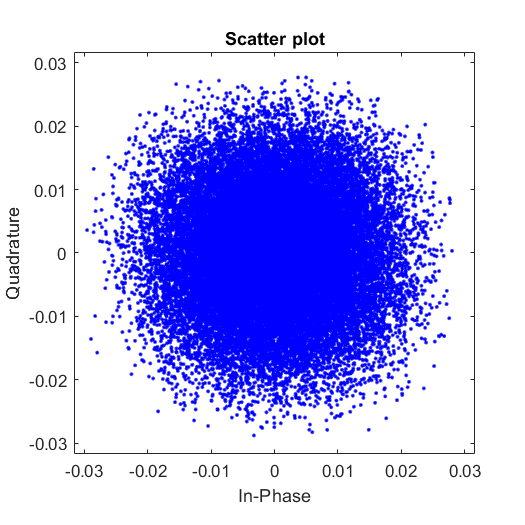

%%% Introduce non-linearities here
upsampled_qpsk = awgn(upsampled_qpsk,20,"measured");

% Power Scaling
measured_power =  mean(abs(upsampled_qpsk).^2);
target_power = 10^-3;

upsampled_qpsk=upsampled_qpsk.*sqrt(target_power/measured_power);
measured_power =  mean(abs(upsampled_qpsk).^2);
% Power Scaling

%%% To test, reduce power until non-linearities drop to 0 $OCCURS AT 0.016$


%%% Further sanity check
%%% Invert applied parameters (>>Ideal back propagation<<)
%%% invert z or equivalent beta_2,gamma,alpha
num_steps = z/dz;
x = upsampled_qpsk.';

for i=1:num_steps

    eDh = exp(-(1j*beta_2.*w.*w + alpha)*dz/2);
    
    eNh = exp(-gamma*1j*dz.*(abs(x).^2));
    
    x = ifft(eDh.*fft(eNh.*x));
    
end

scatterplot(x.',upsampling,0,'b.');

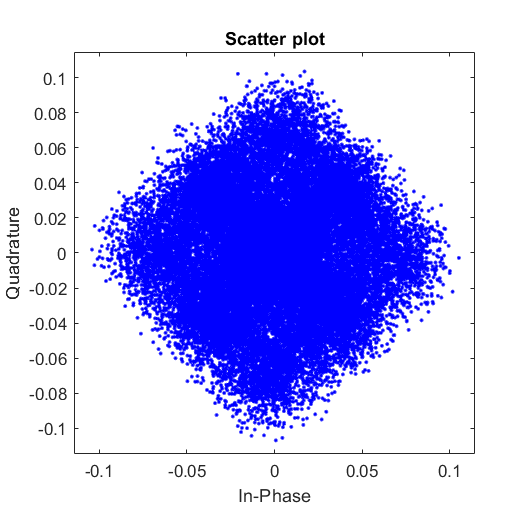

noisy_signal = x;

downsampled_qpsk = rx_ps_filter(noisy_signal).';


CD_Static_Filter = CD_Filter(symbol_rate,D,z,lambda);

downsampled_qpsk = fftfilt(CD_Static_Filter,downsampled_qpsk);
scatterplot(downsampled_qpsk,2);

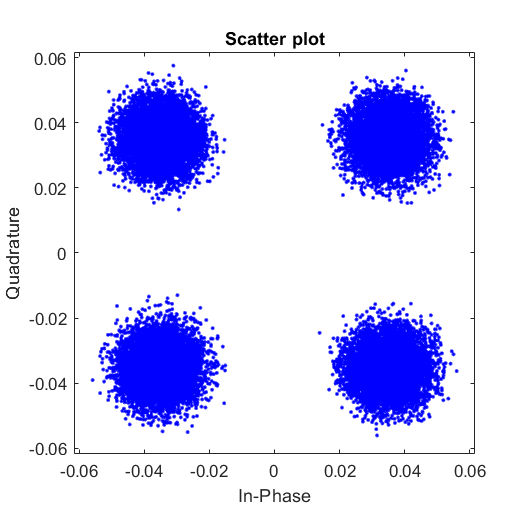


if mean(abs(downsampled_qpsk(2:2:end)).^2)>mean(abs(downsampled_qpsk(1:2:end)).^2)
   moded_qpsk=downsampled_qpsk(2:2:end);
else
   moded_qpsk=downsampled_qpsk(1:2:end);
end

chunk_length = 32768;
moded_qpsk = phase_correction(moded_qpsk.',chunk_length);
scatterplot(moded_qpsk(50:end));


lag = finddelay(qpsk_mod,moded_qpsk);

if lag > 0
    moded_qpsk = moded_qpsk(1+lag:end);
    symbols_q = symbols_q(1:end-lag);
else
    lag = abs(lag);
    moded_qpsk = moded_qpsk(1:end-lag);
    symbols_q = symbols_q(1+lag:end);
end

qpsk = pskdemod(moded_qpsk,4,pi/4,'gray');


[ERRORS,BER] = biterr(symbols_q,qpsk,log2(4))

ERRORS = 0

BER = 0

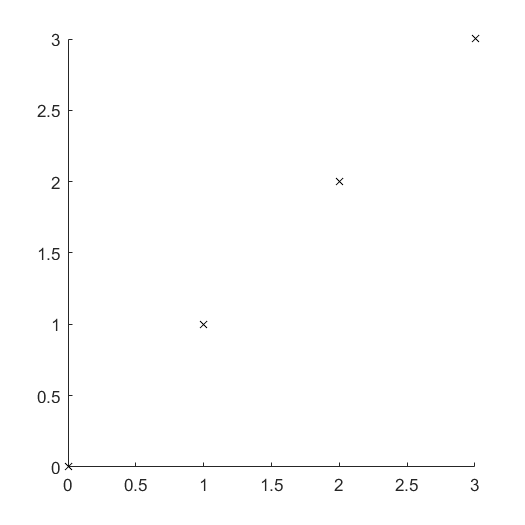

scatter(symbols_q,qpsk,'kx');